# Season 4: Stability Analysis, State Feedback, and LQR

**Learning Outcomes:**

- Analyze system stability using eigenvalues, Lyapunov theory, and BIBO criteria

- Solve Lyapunov equations for continuous and discrete systems

- Test matrix definiteness using Cholesky decomposition

- Design state feedback controllers using pole placement

- Apply LQR (Linear Quadratic Regulator) for optimal control

- Understand and solve Riccati equations

- Design digital controllers using discretization

**Prerequisites:** Seasons 1-3

**MATLAB Version:** R2025b

**Toolboxes Required:** Control System Toolbox

close all; clear; clc;
rng(0);

## Section 4.1: Stability - Eigenvalue Analysis

**Mathematical Background**

For continuous-time system $\dot{x} = Ax$:

- **Stable**: all eigenvalues have Re(λ) < 0

- **Marginally stable**: eigenvalues on imaginary axis, none with Re(λ) > 0

- **Unstable**: at least one eigenvalue with Re(λ) > 0

For discrete-time system $x[k+1] = Ax[k]$:

- **Stable**: all eigenvalues have `λ` < 1

- **Unstable**: at least one eigenvalue with `λ` ≥ 1

Example 1: Stable system

A_stable = [-1  0;
             0 -2];

eig_stable = eig(A_stable);
fprintf('Example 1: Stable system\n');

Example 1: Stable system


fprintf('A =\n'); disp(A_stable);

A =
    -1     0
     0    -2



fprintf('Eigenvalues: ');

Eigenvalues: 

fprintf('%.4f ', eig_stable);

-2.0000 -1.0000 

fprintf('\n');

if all(real(eig_stable) < 0)
    fprintf('✓ STABLE (all eigenvalues have negative real part)\n\n');
else
    fprintf('✗ UNSTABLE\n\n');
end

✓ STABLE (all eigenvalues have negative real part)



Example 2: Unstable system  

A_unstable = [1   0;
              0  -3];

eig_unstable = eig(A_unstable);
fprintf('Example 2: Unstable system\n');

Example 2: Unstable system


fprintf('A =\n'); disp(A_unstable);

A =
     1     0
     0    -3



fprintf('Eigenvalues: ');

Eigenvalues: 

fprintf('%.4f ', eig_unstable);

-3.0000 1.0000 

fprintf('\n');

if all(real(eig_unstable) < 0)
    fprintf('✓ STABLE\n\n');
else
    fprintf('✗ UNSTABLE (eigenvalue at %.4f has positive real part)\n\n', ...
        eig_unstable(find(real(eig_unstable) > 0, 1)));
end

✗ UNSTABLE (eigenvalue at 1.0000 has positive real part)



Example 3: Marginally stable (oscillatory)

A_marginal = [0  1;
             -1  0];

eig_marginal = eig(A_marginal);
fprintf('Example 3: Marginally stable (oscillatory)\n');

Example 3: Marginally stable (oscillatory)


fprintf('A =\n'); disp(A_marginal);

A =
     0     1
    -1     0



fprintf('Eigenvalues: ');

Eigenvalues: 

fprintf('%.4f%+.4fi ', real(eig_marginal), imag(eig_marginal));

0.0000+0.0000i 1.0000-1.0000i 

fprintf('\n');
fprintf('Pure imaginary eigenvalues → Marginally stable (oscillatory)');

Pure imaginary eigenvalues → Marginally stable (oscillatory)

Visualize eigenvalues on complex plane

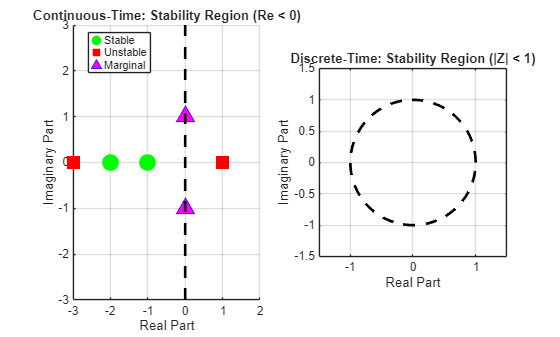

figure('Name', 'Eigenvalue Locations and Stability');
subplot(1,2,1);  % Continuous-time
hold on;
plot(real(eig_stable), imag(eig_stable), 'go', 'MarkerSize', 12, ...
    'MarkerFaceColor', 'g', 'DisplayName', 'Stable');
plot(real(eig_unstable), imag(eig_unstable), 'rs', 'MarkerSize', 12, ...
    'MarkerFaceColor', 'r', 'DisplayName', 'Unstable');
plot(real(eig_marginal), imag(eig_marginal), 'b^', 'MarkerSize', 12, ...
    'MarkerFaceColor', 'magenta', 'DisplayName', 'Marginal');

% Draw stability boundary (imaginary axis)
plot([0 0], [-3 3], 'k--', 'LineWidth', 2, 'HandleVisibility', 'off');
xlim([-3 2]);
ylim([-3 3]);
grid on;
xlabel('Real Part');
ylabel('Imaginary Part');
title('Continuous-Time: Stability Region (Re < 0)');
legend('Location', 'best');

subplot(1,2,2);  % Discrete-time stability region (unit circle)
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k--', 'LineWidth', 2);
hold on;
grid on;
axis equal;
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
xlabel('Real Part');
ylabel('Imaginary Part');
title('Discrete-Time: Stability Region (|Z| < 1)');

## Section 4.2: Lyapunov Stability Theory

**Mathematical Background**

**Lyapunov's Direct Method:**

For $\dot{x} = Ax$, if ∃ positive definite matrix P such that:


$$A^TP + PA = -Q$$


where Q > 0, then the system is asymptotically stable.

**Lyapunov Equation:** $A^TP + PA + Q = 0$

A_lyap = [-1  0.5;
          -0.5 -2];

fprintf('System matrix A:\n');

System matrix A:


disp(A_lyap);

   -1.0000    0.5000
   -0.5000   -2.0000




fprintf('Eigenvalues: ');

Eigenvalues: 

fprintf('%.4f ', eig(A_lyap));

-1.5000 -1.5000 

fprintf('\n\n');

### Solve Lyapunov equation: A'P + PA + Q = 0

Q = eye(2);  % Choose Q = I (positive definite)

Solving Lyapunov equation A^TP + PA + Q = 0 with Q = I:

fprintf('Solution P:\n');

Solution P:


P = lyap(A_lyap', Q);
disp(P);

    0.4815    0.0370
    0.0370    0.2593



Verify solution

residual = A_lyap'*P + P*A_lyap + Q; % must be near zero
fprintf('Residual A^TP + PA + Q:\n');

Residual A^TP + PA + Q:


disp(residual);

   1.0e-15 *

         0   -0.0278
   -0.0278   -0.2220



fprintf('Residual norm: %.2e\n\n', norm(residual));

Residual norm: 2.25e-16



Check if P is positive definite

eig_P = eig(P);
fprintf('Eigenvalues of P: ');

Eigenvalues of P: 

fprintf('%.4f ', eig_P);

0.2532 0.4875 

fprintf('\n');

if all(eig_P > 0)
    fprintf('✓ P is positive definite → System is STABLE\n\n');
else
    fprintf('✗ P is not positive definite → System is UNSTABLE\n\n');
end

✓ P is positive definite → System is STABLE



Try with unstable system

A_unstable_lyap = [0.5  2;
                   0  1];

fprintf('Testing unstable system:\n');

Testing unstable system:


fprintf('A =\n'); disp(A_unstable_lyap);

A =
    0.5000    2.0000
         0    1.0000



fprintf('Eigenvalues:\n');disp(eig(A_unstable_lyap));

Eigenvalues:
    0.5000
    1.0000



The "try ... catch" block is used to handle errors safely.

MATLAB first runs the code inside the "try" section.

If everything runs correctly, it skips the "catch" section.

But if an error happens (for example, the Lyapunov equation cannot be solved), MATLAB immediately jumps to the "catch" section instead of stopping the program.

This lets you handle the error gracefully — for example, by printing a message instead of crashing the script. use " help try" to read more.

try 
    P_unstable = lyap(A_unstable_lyap', Q);
    fprintf('P computed:\n');
    disp(P_unstable);
    fprintf('Eigenvalues of P: ');
    fprintf('%.4f ', eig(P_unstable));
    fprintf('\n');
catch ME
    fprintf('✓ Lyapunov equation has no solution\n');
end

P computed:


   -1.0000    1.3333
    1.3333   -3.1667



Eigenvalues of P: 

-3.8013 -0.3654 

The Lyapunov equation always has a formal solution,but only for stable A will P be positive definite.

Negative eigenvalues of P confirm the system is unstable.

## Section 4.3: Matrix Definiteness and Cholesky Decomposition

**Concept Overview**

A symmetric matrix M is:

- **Positive definite**: x^T M x > 0 for all x ≠ 0

- **Positive semi-definite**: x^T M x ≥ 0

**Cholesky Test:** M > 0 ⟺ M = L L^T exists (L lower triangular)

Positive definite matrix

M_pd = [4  1;
        1  3];

fprintf('Matrix M:\n');

Matrix M:


disp(M_pd);

     4     1
     1     3



Test using Cholesky decomposition

try
    L = chol(M_pd, 'lower');
    fprintf('Cholesky decomposition succeeded:\n');
    fprintf('L (lower triangular):\n');
    disp(L);
    fprintf('Verification L*L^T:\n');
    disp(L*L');
    fprintf('✓ Matrix is POSITIVE DEFINITE\n\n');
catch
    fprintf('✗ Matrix is NOT positive definite\n\n');
end

Cholesky decomposition succeeded:


L (lower triangular):


    2.0000         0
    0.5000    1.6583



Verification L*L^T:


     4     1
     1     3



✓ Matrix is POSITIVE DEFINITE



Check eigenvalues

fprintf('Eigenvalues of M: ');

Eigenvalues of M: 

fprintf('%.4f ', eig(M_pd));

2.3820 4.6180 

fprintf('All positive → positive definite\n\n');

All positive → positive definite



Not positive definite matrix

M_nd = [1  2;
        2  1];

fprintf('Testing semi-definite matrix:\n');

Testing semi-definite matrix:


fprintf('M =\n'); disp(M_nd);

M =
     1     2
     2     1




try
    L_nd = chol(M_nd, 'lower');
    fprintf('✓ Positive definite\n');
catch
    fprintf('✗ NOT positive definite (Cholesky failed)\n');
end

✗ NOT positive definite (Cholesky failed)



fprintf('Eigenvalues: ');

Eigenvalues: 

fprintf('%.4f ', eig(M_nd));

-1.0000 3.0000 

fprintf('(Has negative eigenvalue)\n\n');

(Has negative eigenvalue)



## Section 4.4: BIBO Stability

**Mathematical Background**

**Bounded-Input Bounded-Output (BIBO) Stability:**

System is BIBO stable if bounded input produces bounded output.

For LTI systems: BIBO stable ⟺ all poles have Re(s) < 0

Create transfer functions

num1 = [1];
den1 = [1 3 2];  % Poles at s = -1, -2

num2 = [1];
den2 = [1 -1 -2];  % Poles at s = -2, +1

fprintf('Transfer Function 1:\n');

Transfer Function 1:


G1 = tf(num1, den1)


G1 =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.


poles1 = pole(G1);
fprintf('Poles: ');

Poles: 

fprintf('%.4f ', poles1);

-2.0000 -1.0000 

fprintf('\n');
if all(real(poles1) < 0)
    fprintf('✓ BIBO STABLE\n\n');
else
    fprintf('✗ BIBO UNSTABLE\n\n');
end

✓ BIBO STABLE




fprintf('Transfer Function 2:\n');

Transfer Function 2:


G2 = tf(num2, den2)


G2 =
 
       1
  -----------
  s^2 - s - 2
 
Continuous-time transfer function.


poles2 = pole(G2);
fprintf('Poles: ');

Poles: 

fprintf('%.4f ', poles2);

2.0000 -1.0000 

fprintf('\n');
if all(real(poles2) < 0)
    fprintf('✓ BIBO STABLE\n\n');
else
    fprintf('✗ BIBO UNSTABLE (pole at s = %.2f)\n\n', poles2(real(poles2)>0));
end

✗ BIBO UNSTABLE (pole at s = 2.00)



Demonstrate with step response

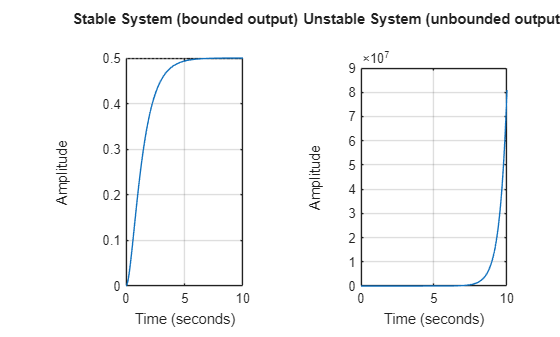

figure('Name', 'BIBO Stability Comparison');
subplot(1,2,1);
step(G1, 10);
grid on;
title('Stable System (bounded output)');
subplot(1,2,2);
try
    step(G2, 10);
    grid on;
    title('Unstable System (unbounded output)');
catch
    fprintf('Unstable system produces unbounded output\n');
end

## Section 4.5: State Feedback and Pole Placement

**Mathematical Background**

State feedback: $u = -Kx + r$

Closed-loop system: $\dot{x} = (A - BK)x + Br$

**Goal:** Choose K to place closed-loop poles at desired locations

**Requirement:** System must be controllable

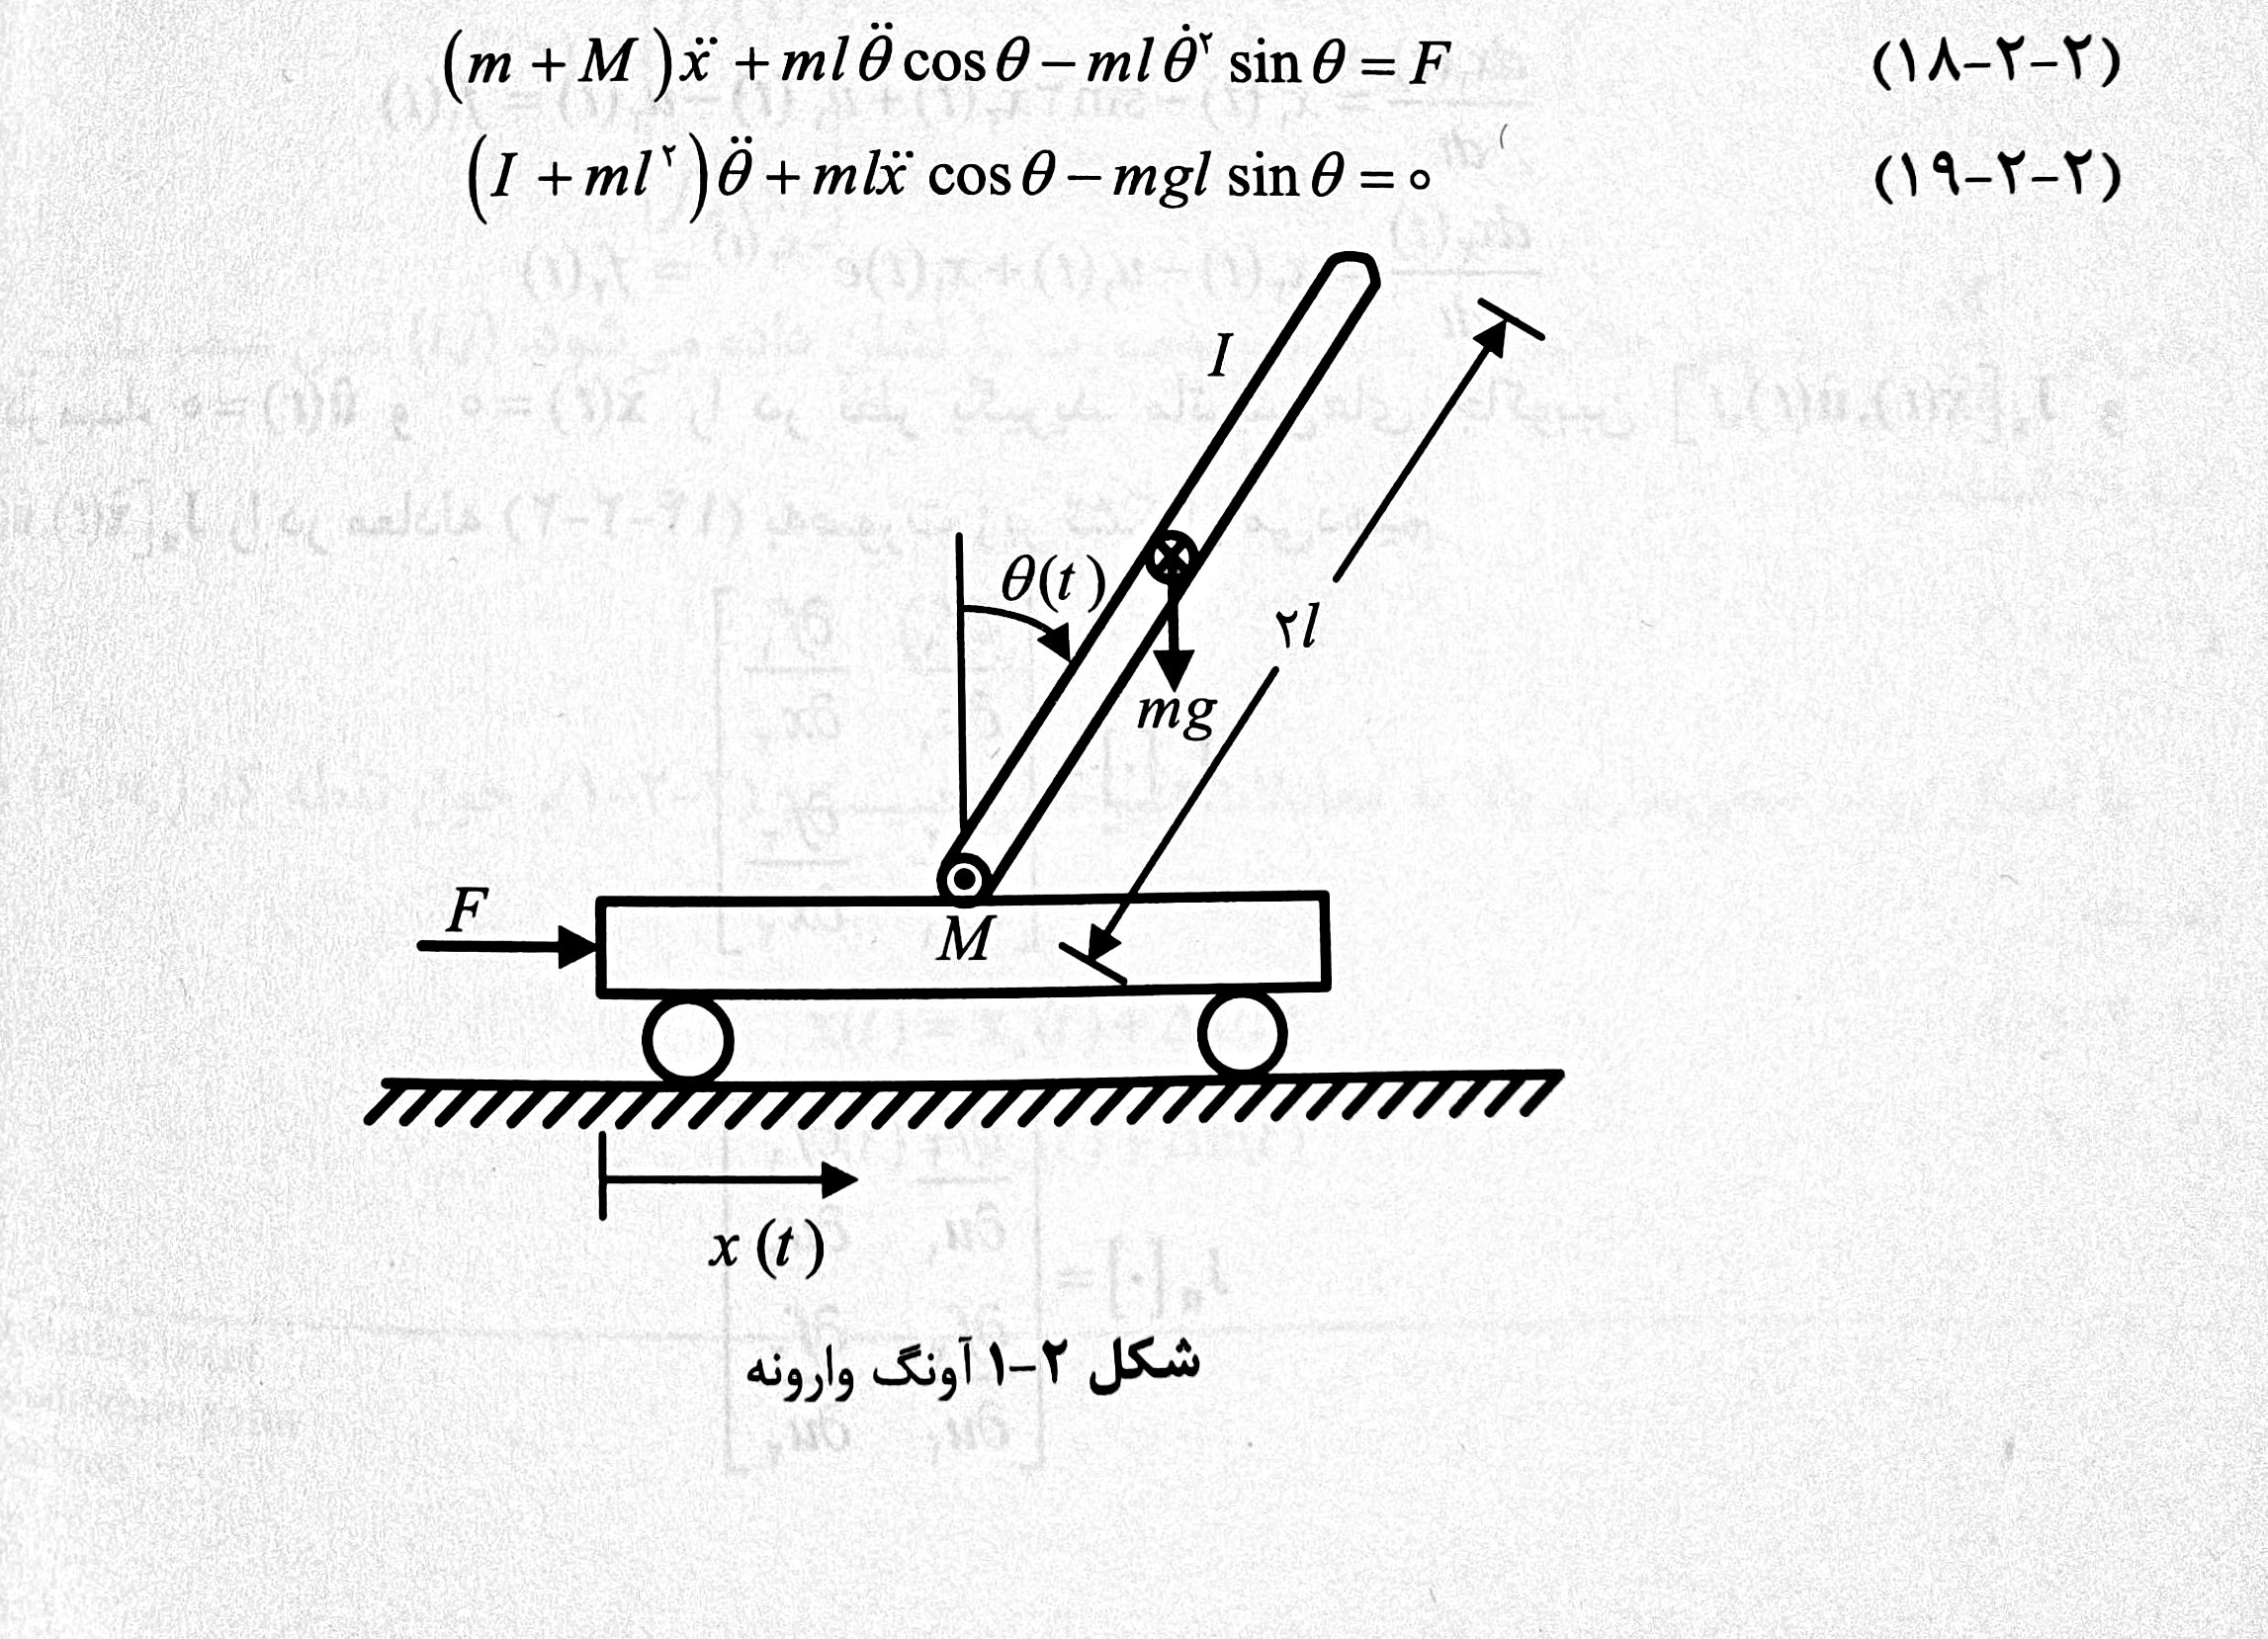

Page 36. Modern Control Fundamentals - A. Khaki Sedigh

syms m M l I g real
syms x dx th dth F real

X  = [x; dx; th; dth];
u  = sym('F','real');

syms ddx ddth real

eq1 = (m+M)*ddx + m*l*ddth*cos(th) - m*l*dth^2*sin(th) - F == 0;
eq2 = (I + m*l^2)*ddth + m*l*ddx*cos(th) - m*g*l*sin(th) == 0;

S = solve([eq1, eq2],[ddx, ddth],'ReturnConditions',false);
ddx_expr  = simplify(S.ddx);
ddth_expr = simplify(S.ddth);

f = [ dx;
      ddx_expr;
      dth;
      ddth_expr ];

% Linearize: at upright equilibrium (x=0,dx=0,th=0,dth=0,u=0)
A_sym = jacobian(f, X);
B_sym = jacobian(f, u);

x_eq = [0; 0; 0; 0];
u_eq = 0;

A = simplify(subs(A_sym, [X; u], [x_eq; u_eq]));
B = simplify(subs(B_sym, [X; u], [x_eq; u_eq]));

C = eye(4);
D = zeros(4,1);

disp('A ='); disp(A);

A =


$$\left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{g\,l^{2}\,m^{2}}{M\,m\,l^{2}+\text{I}\,m+\text{I}\,M} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{g\,l\,m\,\left(M+m\right)}{M\,m\,l^{2}+\text{I}\,m+\text{I}\,M} & 0 \end{array}\right)$$

disp('B ='); disp(B);

B =


$$\left(\begin{array}{c} 0\\ \frac{m\,l^{2}+\text{I}}{M\,m\,l^{2}+\text{I}\,m+\text{I}\,M}\\ 0\\ -\frac{l\,m}{M\,m\,l^{2}+\text{I}\,m+\text{I}\,M} \end{array}\right)$$

disp('C ='); disp(C);

C =
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



disp('D ='); disp(D);

D =
     0
     0
     0
     0



m_val = 0.6;     % pendulum mass [kg]
M_val = 0.5;     % cart mass [kg]
l_val = 0.3;     % COM distance [m]
I_val = 0.006;   % pendulum inertia about COM [kg·m^2]
g_val = 9.81;    % gravity [m/s^2]

A_pend = double(subs(A, [m M l I g], [m_val M_val l_val I_val g_val]));
B_pend = double(subs(B, [m M l I g], [m_val M_val l_val I_val g_val]));

disp('A (numeric) ='); disp(A_pend);

A (numeric) =
         0    1.0000         0         0
         0         0   -9.4596         0
         0         0         0    1.0000
         0         0   57.8089         0




disp('B (numeric) ='); disp(B_pend);

B (numeric) =
         0
    1.7857
         0
   -5.3571




fprintf('Inverted pendulum system (4 states):\n');

Inverted pendulum system (4 states):


fprintf('Open-loop eigenvalues: ');

Open-loop eigenvalues: 

fprintf('%.4f ', eig(A_pend));

0.0000 0.0000 7.6032 -7.6032 

fprintf('\n');
fprintf('System is UNSTABLE (positive eigenvalues)\n\n');

System is UNSTABLE (positive eigenvalues)



Check controllability

C_ctrb = ctrb(A_pend, B_pend);
if rank(C_ctrb) == size(A_pend, 1)
    fprintf('✓ System is controllable → Pole placement possible\n\n');
    fprintf('The controllability rank is: %d',rank(C_ctrb));
    fprintf('The rank is: %d',size(A_pend,1));
else
    fprintf('✗ System not controllable → Cannot place all poles\n\n');
    fprintf('The controllability rank is: %d',rank(C_ctrb));
    fprintf('The rank is: %d',size(A_pend,1));
end

✓ System is controllable → Pole placement possible



The controllability rank is: 4

The rank is: 4

Desired pole locations (all in left half-plane for stability)

poles_desired = [-1, -1.5, -2, -2.5];

fprintf('Desired closed-loop poles: ');

Desired closed-loop poles: 

fprintf('%.4f ', poles_desired);

-1.0000 -1.5000 -2.0000 -2.5000 

Design state feedback using place

K = place(A_pend, B_pend, poles_desired);

fprintf('State feedback gain K:\n');

State feedback gain K:


disp(K);

   -0.1427   -0.3663  -14.1519   -1.4288



Closed-loop system

A_cl = A_pend - B_pend*K;
fprintf('Closed-loop eigenvalues: ');

Closed-loop eigenvalues: 

fprintf('%.4f ', eig(A_cl));

-2.5000 -2.0000 -1.5000 -1.0000 

Verify poles are at desired locations

pole_error = sort(eig(A_cl)) - sort(poles_desired)';
fprintf('Pole placement error: %.2e\n\n', norm(pole_error));

Pole placement error: 3.16e-13



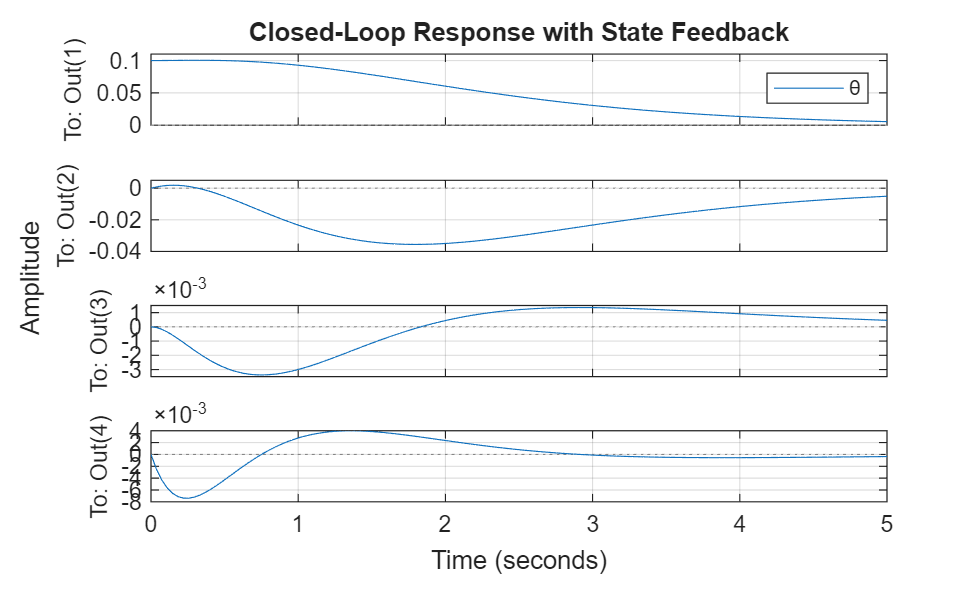


% Simulate closed-loop response
sys_cl = ss(A_cl, B_pend, eye(4), 0);
x0 = [0.1; 0; 0; 0];  % Initial angle perturbation

figure('Name', 'Pole Placement - Inverted Pendulum');
initial(sys_cl, x0, 5);
grid on;
title('Closed-Loop Response with State Feedback');
legend('θ', 'dθ/dt', 'x', 'dx/dt');

## Section 4.6: Ackermann's Formula

**Mathematical Background**

For single-input systems (m=1):


$$K = [0\ 0\ \ldots\ 0\ 1] \mathcal{C}^{-1} \alpha(A)$$


where α(s) is desired characteristic polynomial

A_acker = [0  1; -2 -3];
B_acker = [0; 1];

fprintf('Second-order system:\n');

Second-order system:


fprintf('A =\n'); disp(A_acker);

A =
     0     1
    -2    -3



fprintf('B =\n'); disp(B_acker);

B =
     0
     1




% Desired poles
p1 = -4;
p2 = -5;
fprintf('Desired poles: %.1f, %.1f\n', p1, p2);

Desired poles: -4.0, -5.0



% Using acker function
K_acker = acker(A_acker, B_acker, [p1 p2]);
fprintf('Gain using acker(): K = [%.4f  %.4f]\n', K_acker);

Gain using acker(): K = [18.0000  6.0000]



% Using place function for comparison
K_place = place(A_acker, B_acker, [p1 p2]);

fprintf('Gain using place():  K = [%.4f  %.4f]\n', K_place);

Gain using place():  K = [18.0000  6.0000]


fprintf('Difference: %.2e\n\n', norm(K_acker - K_place));

Difference: 7.32e-15




% Verify closed-loop poles
A_cl_acker = A_acker - B_acker*K_acker;
fprintf('Closed-loop poles: ');

Closed-loop poles: 

fprintf('%.4f ', eig(A_cl_acker));

-4.0000 -5.0000 

fprintf('\n\n');

## Section 4.8: LQR - Linear Quadratic Regulator

**Mathematical Background**

**(This topic is covered in Season 8 (Optimal Control) of Control Modern Fundamentals by A. Khaki Sedigh, which is not covered in class. Still useful to know and use.)**

**LQR Problem:** Minimize cost function


$$J = \int_0^{\infty} (x^TQx + u^TRu)dt$$


**Solution:** $u = -Kx$ where $K = R^{-1}B^TP$

P solves Continuous Algebraic Riccati Equation (CARE):


$$A^TP + PA - PBR^{-1}B^TP + Q = 0$$


A_lqr = [0  1; -1 -0.5];
B_lqr = [0; 1];
C_lqr = [1 0];
D_lqr = 0;

fprintf('System:\n');

System:


fprintf('A =\n'); disp(A_lqr);

A =
         0    1.0000
   -1.0000   -0.5000



fprintf('B =\n'); disp(B_lqr);

B =
     0
     1




% Design parameters
Q_lqr = diag([10, 1]);  % Penalize position more than velocity
R_lqr = 1;              % Input cost

fprintf('Cost matrices:\n');

Cost matrices:


fprintf('Q (state cost) =\n'); disp(Q_lqr);

Q (state cost) =
    10     0
     0     1



fprintf('R (input cost) = %.1f\n\n', R_lqr);

R (input cost) = 1.0




% Solve LQR
[K_lqr, S, poles_lqr] = lqr(A_lqr, B_lqr, Q_lqr, R_lqr);

fprintf('LQR Results:\n');

LQR Results:


fprintf('Optimal gain K = [%.4f  %.4f]\n', K_lqr);

Optimal gain K = [2.3166  1.9255]


fprintf('Solution to Riccati equation S:\n'); disp(S);

Solution to Riccati equation S:
    7.5446    2.3166
    2.3166    1.9255



fprintf('Closed-loop poles: ');

Closed-loop poles: 

fprintf('%.4f ', poles_lqr);

-1.2128 -1.2128 


% Verify S satisfies CARE: A'S + SA - SBR^(-1)B'S + Q = 0
CARE_residual = A_lqr'*S + S*A_lqr - S*B_lqr*(R_lqr\B_lqr')*S + Q_lqr;
fprintf('CARE residual norm: %.2e\n\n', norm(CARE_residual));

CARE residual norm: 4.00e-15



Compare responses with different Q matrices

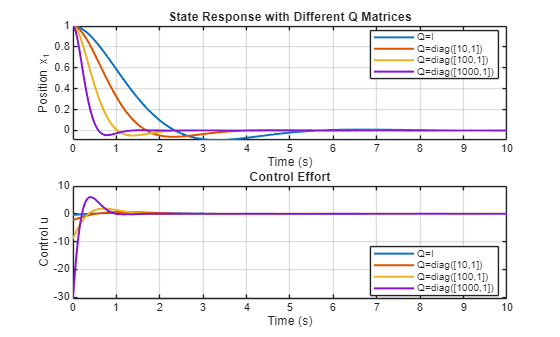

Q_values = {eye(2), diag([10,1]), diag([100,1]), diag([1000,1])};
Q_labels = {'Q=I', 'Q=diag([10,1])', 'Q=diag([100,1])', 'Q=diag([1000,1])'};

figure('Name', 'LQR - Effect of Q Matrix');
x0 = [1; 0];

for i = 1:length(Q_values)
    [K_temp, ~, ~] = lqr(A_lqr, B_lqr, Q_values{i}, R_lqr);
    A_cl_temp = A_lqr - B_lqr*K_temp;
    sys_cl_temp = ss(A_cl_temp, zeros(2,1), C_lqr, 0);
    
    [y, t, x] = initial(sys_cl_temp, x0, 10);
    
    subplot(2,1,1);
    plot(t, x(:,1), 'LineWidth', 1.5, 'DisplayName', Q_labels{i});
    hold on;
    
    % Compute control effort
    u = -K_temp * x';
    subplot(2,1,2);
    plot(t, u, 'LineWidth', 1.5, 'DisplayName', Q_labels{i});
    hold on;
end

subplot(2,1,1);
grid on;
xlabel('Time (s)');
ylabel('Position x_1');
title('State Response with Different Q Matrices');
legend('Location', 'best');

subplot(2,1,2);
grid on;
xlabel('Time (s)');
ylabel('Control u');
title('Control Effort');
legend('Location', 'best');


fprintf('Observation: Larger Q₁ → faster response but higher control effort\n\n');

Observation: Larger Q₁ → faster response but higher control effort



## Section 4.9: Solving Riccati Equation Directly

**Using care() and dare() for CARE and DARE**

A_ricc = [0 1; -2 -3];
B_ricc = [0; 1];
Q_ricc = eye(2);
R_ricc = 1;

fprintf('Continuous-time Algebraic Riccati Equation (CARE):\n');

Continuous-time Algebraic Riccati Equation (CARE):


fprintf('A^TP + PA - PBR^(-1)B^TP + Q = 0\n\n');

A^TP + PA - PBR^(-1)B^TP + Q = 0




% Solve using care
[P_care, ~, K_care] = care(A_ricc, B_ricc, Q_ricc, R_ricc);

fprintf('Solution P (using care):\n');

Solution P (using care):


disp(P_care);

    1.2361    0.2361
    0.2361    0.2361




fprintf('Optimal gain K = R^(-1)B^TP:\n');

Optimal gain K = R^(-1)B^TP:


disp(K_care);

    0.2361    0.2361




% Compare with lqr
[K_lqr_comp, P_lqr_comp] = lqr(A_ricc, B_ricc, Q_ricc, R_ricc);

fprintf('Comparison with lqr():\n');

Comparison with lqr():


disp('P using CARE:'); disp(P_care);

P using CARE:
    1.2361    0.2361
    0.2361    0.2361



disp('P using LQR:'); disp(P_lqr_comp);

P using LQR:
    1.2361    0.2361
    0.2361    0.2361



fprintf('Difference in P: %.2e\n', norm(P_care - P_lqr_comp));

Difference in P: 2.24e-16


disp('K using CARE:'); disp(K_care);

K using CARE:
    0.2361    0.2361



disp('K using LQR:'); disp(K_lqr_comp);

K using LQR:
    0.2361    0.2361



fprintf('Difference in K: %.2e\n\n', norm(K_care - K_lqr_comp));

Difference in K: 1.76e-16



Discrete-time Riccati equation

There is a function for Discrete-time Riccati equation (DARE) which you can use by utilizing:

for the sake of staying on topic, we will skip it.

## Section 4.10: Summary and Key Takeaways

**Key Concepts Covered:**

- Stability analysis: eigenvalues, Lyapunov, BIBO

- Lyapunov equations: `lyap`, `dlyap`

- Matrix definiteness: Cholesky decomposition

- State feedback: pole placement with `place`, `acker`

- Optimal control: LQR design with `lqr`, `dlqr`

- Riccati equations: `care`, `dare`

- Digital control: discretization and discrete LQR

**MATLAB Functions Mastered:**

`eig`, `lyap`, `dlyap`, `chol`, `place`, `acker`, `lqr`, `dlqr`, `care`, `dare`, `c2d`, `d2c`, `pole`

**Design Trade-offs:**

- Q matrix: penalizes state deviation (larger = faster response)

- R matrix: penalizes control effort (larger = less aggressive)

- Pole placement: direct control over dynamics

- LQR: optimal balance between performance and effort